# Project 1

## Theoretical Validation

clear; clc;

### General Cases

e = [0;0;0];
I = [3 0 0; 0 2 0; 0 0 1];
b3_hat = [0;0;1];

#### Null Case

w_0 = [0;0;0];
w_0_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;0];

out_null = runModel(I, g, w_0, e, b3_hat);

e_null = out_null.angle_out(end,:)

e_null =      0     0     0


w_null = out_null.omega(end,:)

w_null =      0     0     0


w_body_null = out_null.omega(end,:)

w_body_null =      0     0     0


h_null = out_null.ang_mom(end,:)

h_null =      0     0     0


h_body_null = out_null.ang_mom_body(end,:)

h_body_null =      0     0     0


#### Constant Rotation Case 1

w_0 = [1;0;0];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;0];

out_constant1 = runModel(I, g, w_0, e, b3_hat);

e_constant1 = out_constant1.angle_out(out_constant1.tout == 2, :)

e_constant1 =          0    2.0000         0


w_constant1 = out_constant1.omega(out_constant1.tout == 2, :)

w_constant1 =      1     0     0


w_body_constant1 = out_constant1.omega_body(out_constant1.tout == 2, :)

w_body_constant1 =      1     0     0


h_constant1 = out_constant1.ang_mom(out_constant1.tout == 2, :)

h_constant1 =      3     0     0


h_body_constant1 = out_constant1.ang_mom_body(out_constant1.tout == 2, :)

h_body_constant1 =      3     0     0


#### Constant Rotation Case 2

w_0 = [0;1;0];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;0];

out_constant2 = runModel(I, g, w_0, e, b3_hat);

e_constant2 = out_constant2.angle_out(out_constant2.tout == 2, :)

e_constant2 =     1.5708    2.0000   -1.5708


w_constant2 = out_constant2.omega(out_constant2.tout == 2, :)

w_constant2 =      0     1     0


w_body_constant2 = out_constant2.omega_body(out_constant2.tout == 2, :)

w_body_constant2 =      0     1     0


h_constant2 = out_constant2.ang_mom(out_constant2.tout == 2, :)

h_constant2 =      0     2     0


h_body_constant2 = out_constant2.ang_mom_body(out_constant2.tout == 2, :)

h_body_constant2 =      0     2     0


#### Constant Rotation Case 3

w_0 = [0;0;1];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;0];

out_constant3 = runModel(I, g, w_0, e, b3_hat);


e_constant3 = out_constant3.angle_out(out_constant3.tout == 2, :)

e_constant3 =     2.0000         0         0


w_constant3 = out_constant3.omega(out_constant3.tout == 2, :)

w_constant3 =      0     0     1


w_body_constant3 = out_constant3.omega_body(out_constant3.tout == 2, :)

w_body_constant3 =      0     0     1


h_constant3 = out_constant3.ang_mom(out_constant3.tout == 2, :)

h_constant3 =      0     0     1


h_body_constant3 = out_constant3.ang_mom_body(out_constant3.tout == 2, :)

h_body_constant3 =      0     0     1


#### Constant Torque Case 1

w_0 = [0;0;0];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [1;0;0];

out_torque1 = runModel(I, g, w_0, e, b3_hat);

e_torque1 = out_torque1.angle_out(out_torque1.tout == 3, :)

e_torque1 =          0    1.5000         0


w_torque1 = out_torque1.omega(out_torque1.tout == 3, :)

w_torque1 =     1.0000         0         0


w_body_torque1 = out_torque1.omega_body(out_torque1.tout == 3, :)

w_body_torque1 =     1.0000         0         0


h_torque1 = out_torque1.ang_mom(out_torque1.tout == 3, :)

h_torque1 =     3.0000         0         0


h_body_torque1 = out_torque1.ang_mom_body(out_torque1.tout == 3, :)

h_body_torque1 =     3.0000         0         0


#### Constant Torque Case 2

w_0 = [0;0;0];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;1;0];

out_torque2 = runModel(I, g, w_0, e, b3_hat);

e_torque2 = out_torque2.angle_out(out_torque2.tout == 3, :)

e_torque2 =     1.5708    2.2500   -1.5708


w_torque2 = out_torque2.omega(out_torque2.tout == 3, :)

w_torque2 =          0    1.5000         0


w_body_torque2 = out_torque2.omega_body(out_torque2.tout == 3, :)

w_body_torque2 =          0    1.5000         0


h_torque2 = out_torque2.ang_mom(out_torque2.tout == 3, :)

h_torque2 =          0    3.0000         0


h_body_torque2 = out_torque2.ang_mom_body(out_torque2.tout == 3, :)

h_body_torque2 =          0    3.0000         0


#### Constant Torque Case 3

w_0 = [0;0;0];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;1];

out_torque3 = runModel(I, g, w_0, e, b3_hat);


e_torque3 = [2*pi, 0, 0] + out_torque3.angle_out(out_torque3.tout == 3, :)

e_torque3 =     4.5000         0         0


w_torque3 = out_torque3.omega(out_torque3.tout == 3, :)

w_torque3 =          0         0    3.0000


w_body_torque3 = out_torque3.omega_body(out_torque3.tout == 3, :)

w_body_torque3 =          0         0    3.0000


h_torque3 = out_torque3.ang_mom(out_torque3.tout == 3, :)

h_torque3 =          0         0    3.0000


h_body_torque3 = out_torque3.ang_mom_body(out_torque3.tout == 3, :)

h_body_torque3 =          0         0    3.0000


### Specific Cases

e = [0;0;0];
b3_hat = [0;0;1];

#### Isoinertial Case

I = [1 0 0; 0 1 0; 0 0 1];
w_0 = [1;0;0];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;2;0];

out_iso = runModel(I, g, w_0, e, b3_hat);

e_iso = out_iso.angle_out(out_iso.tout == 2, :);
w_iso = out_iso.omega(out_iso.tout == 2, :)

w_iso =     1.0000    4.0000         0


w_body_iso = out_iso.omega_body(out_iso.tout == 2, :);
h_iso = out_iso.ang_mom(out_iso.tout == 2, :)

h_iso =     1.0000    4.0000         0


h_body_iso = out_iso.ang_mom_body(out_iso.tout == 2, :);

#### Axisymmetric Prolate Case

I_t = 2;
I_a = 10;
I = [I_t 0 0; 0 I_t 0; 0 0 I_a];
w_0 = [0.5;0.5;1];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;0];

out_axypro = runModel(I, g, w_0, e, b3_hat);

e_axypro = out_axypro.angle_out(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :);
w_axypro = out_axypro.omega(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :)

w_axypro =     0.4996    0.5004    1.0000


w_body_axypro = out_axypro.omega_body(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :);
h_axypro = out_axypro.ang_mom(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :)

h_axypro =     0.9992    1.0008   10.0000


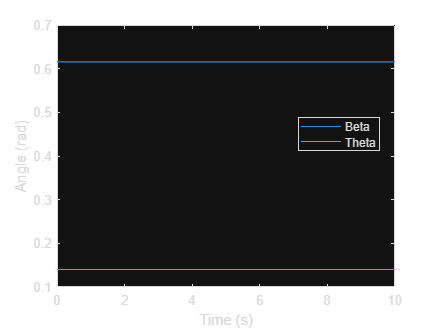

h_body_axypro = out_axypro.ang_mom_body(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :);

beta = acos(out_axypro.omega(:,3)./vecnorm(out_axypro.omega, 2, 2));
theta = acos(out_axypro.ang_mom(:,3)./vecnorm(out_axypro.ang_mom, 2, 2));

figure
plot(out_axypro.tout, beta, out_axypro.tout, theta)
xlabel("Time (s)")
ylabel("Angle (rad)")
legend("Beta", "Theta", "Location", "best")

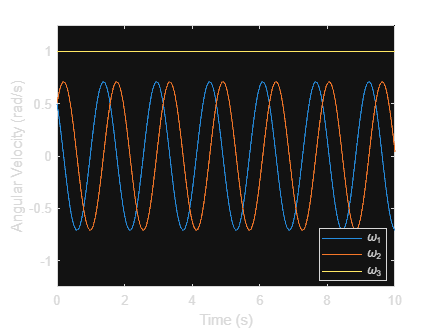


figure
plot(out_axypro.tout, out_axypro.omega(:,1), out_axypro.tout, out_axypro.omega(:,2), out_axypro.tout, out_axypro.omega(:,3))
ylim([-1.25, 1.25])
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")
legend("\omega_1", "\omega_2", "\omega_3", "Location", "best")

#### Axisymmetric Oblate Case

I_t = 10;
I_a = 2;
I = [I_t 0 0; 0 I_t 0; 0 0 I_a];
w_0 = [0.05;0.05;1];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;0];

out_axyob = runModel(I, g, w_0, e, b3_hat);

e_axyob = out_axyob.angle_out(abs(out_axyob.tout - 5*pi/2) == min(abs(out_axyob.tout - 5*pi/2)), :);
w_axyob = out_axyob.omega(abs(out_axyob.tout - 5*pi/2) == min(abs(out_axyob.tout - 5*pi/2)), :)

w_axyob =     0.0500    0.0500    1.0000


w_body_axyob = out_axyob.omega_body(abs(out_axyob.tout - 5*pi/2) == min(abs(out_axyob.tout - 5*pi/2)), :);
h_axyob = out_axyob.ang_mom(abs(out_axyob.tout - 5*pi/2) == min(abs(out_axyob.tout - 5*pi/2)), :)

h_axyob =     0.5000    0.5000    2.0000


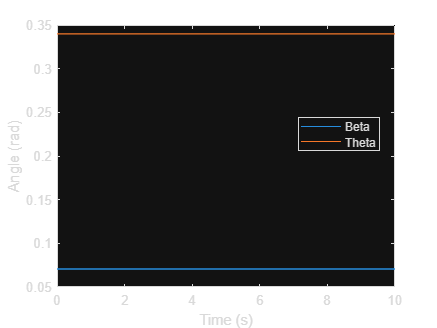

h_body_axyob = out_axyob.ang_mom_body(abs(out_axyob.tout - 5*pi/2) == min(abs(out_axyob.tout - 5*pi/2)), :);

beta = acos(out_axyob.omega(:,3)./vecnorm(out_axyob.omega, 2, 2));
theta = acos(out_axyob.ang_mom(:,3)./vecnorm(out_axyob.ang_mom, 2, 2));

figure
plot(out_axyob.tout, beta, out_axyob.tout, theta)
xlabel("Time (s)")
ylabel("Angle (rad)")
legend("Beta", "Theta", "Location", "best")

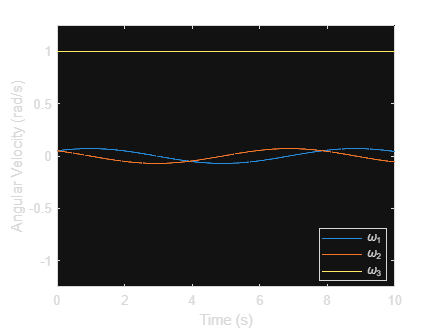


figure
plot(out_axyob.tout, out_axyob.omega(:,1), out_axyob.tout, out_axyob.omega(:,2), out_axyob.tout, out_axyob.omega(:,3))
ylim([-1.25, 1.25])
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")
legend("\omega_1", "\omega_2", "\omega_3", "Location", "best")

#### Trinertial Major Case

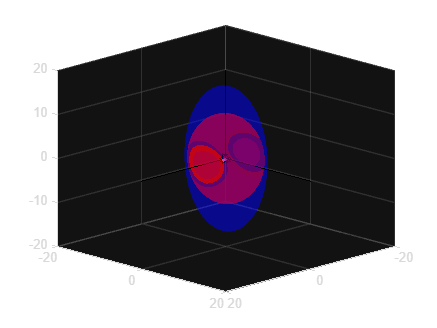

I = [21 0 0; 0 14 0; 0 0 7];
w_0 = [5;3;3];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;0];

out_trimaj = runModel(I, g, w_0, e, b3_hat);

I1 = I(1, 1);
I2 = I(2, 2);
I3 = I(3, 3);

T = (I1*w_0(1)^2 + I2*w_0(2)^2 + I3*w_0(3)^2)*0.5;
h = (I1^2*w_0(1)^2 + I2^2*w_0(2)^2 + I3^2*w_0(3)^2)^0.5;
Ngrid = 500;
 
w1em = sqrt(2*T/I1); w2em = sqrt(2*T/I2); w3em = sqrt(2*T/I3);
[w1e,w2e,w3e]=ellipsoid(0,0,0,w1em,w2em,w3em,Ngrid);
 
w1hm = h/I1; w2hm = h/I2; w3hm = h/I3;
[w1m,w2m,w3m]=ellipsoid(0,0,0,w1hm,w2hm,w3hm,Ngrid);
 
figure
surf(w1e,w2e,w3e,'FaceColor','r','EdgeColor','none','FaceAlpha',.5)
x = 20;
axis([-x x -x x -x x]);
hold on;

% plot momentum ellipsoid
surf(w1m,w2m,w3m,'FaceColor','b','EdgeColor','none','FaceAlpha',.3)

% plot principal axis vectors
plot3([0 x + 0.5],[0 0],[0 0],'k<')
plot3([0 x + 0.5],[0 0],[0 0],'k-')
plot3([0 0],[0 x + 0.5],[0 0],'k-')
plot3([0 0],[0 x + 0.5],[0 0],'k>')
plot3([0 0],[0 0],[0 x + 0.5],'k-')
plot3([0 0],[0 0],[0 x + 0.5],'k^')

% set the view perspective
view(135,20)

% Initialize the vector as a quiver plot (arrows in 3D)
angular_velocity = out_trimaj.omega;
num_steps = size(angular_velocity, 1);
h = quiver3(0, 0, 0, angular_velocity(1, 1), angular_velocity(1, 2), angular_velocity(1, 3), 'MaxHeadSize', 0.5, 'LineWidth', 2);

% Animation loop
for t = 2:num_steps
    % Update the vector with new data for this time step
    set(h, 'UData', angular_velocity(t, 1), 'VData', angular_velocity(t, 2), 'WData', angular_velocity(t, 3));
    
    % Pause to control the speed of the animation
    pause(0.001);  % Adjust pause duration to change animation speed
end
hold off;

#### Trinertial Minor Case

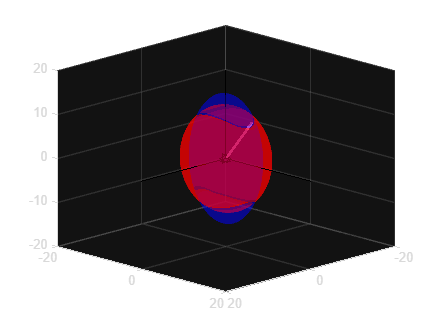

I = [21 0 0; 0 14 0; 0 0 7];
w_0 = [3;3;10];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;0];

out_trimin = runModel(I, g, w_0, e, b3_hat);

I1 = I(1, 1);
I2 = I(2, 2);
I3 = I(3, 3);

T = (I1*w_0(1)^2 + I2*w_0(2)^2 + I3*w_0(3)^2)*0.5;
h = (I1^2*w_0(1)^2 + I2^2*w_0(2)^2 + I3^2*w_0(3)^2)^0.5;
Ngrid = 500;
 
w1em = sqrt(2*T/I1); w2em = sqrt(2*T/I2); w3em = sqrt(2*T/I3);
[w1e,w2e,w3e]=ellipsoid(0,0,0,w1em,w2em,w3em,Ngrid);
 
w1hm = h/I1; w2hm = h/I2; w3hm = h/I3;
[w1m,w2m,w3m]=ellipsoid(0,0,0,w1hm,w2hm,w3hm,Ngrid);
 
figure
surf(w1e,w2e,w3e,'FaceColor','r','EdgeColor','none','FaceAlpha',.5)
x = 20;
axis([-x x -x x -x x]);
hold on;

% plot momentum ellipsoid
surf(w1m,w2m,w3m,'FaceColor','b','EdgeColor','none','FaceAlpha',.3)

% plot principal axis vectors
plot3([0 x + 0.5],[0 0],[0 0],'k<')
plot3([0 x + 0.5],[0 0],[0 0],'k-')
plot3([0 0],[0 x + 0.5],[0 0],'k-')
plot3([0 0],[0 x + 0.5],[0 0],'k>')
plot3([0 0],[0 0],[0 x + 0.5],'k-')
plot3([0 0],[0 0],[0 x + 0.5],'k^')

% set the view perspective
view(135,20)

% Initialize the vector as a quiver plot (arrows in 3D)
angular_velocity = out_trimin.omega;
num_steps = size(angular_velocity, 1);
h = quiver3(0, 0, 0, angular_velocity(1, 1), angular_velocity(1, 2), angular_velocity(1, 3), 'MaxHeadSize', 0.5, 'LineWidth', 2);

% Animation loop
for t = 2:num_steps
    % Update the vector with new data for this time step
    set(h, 'UData', angular_velocity(t, 1), 'VData', angular_velocity(t, 2), 'WData', angular_velocity(t, 3));
    
    % Pause to control the speed of the animation
    pause(0.001);  % Adjust pause duration to change animation speed
end
hold off;

#### Trinertial Intermediate Case

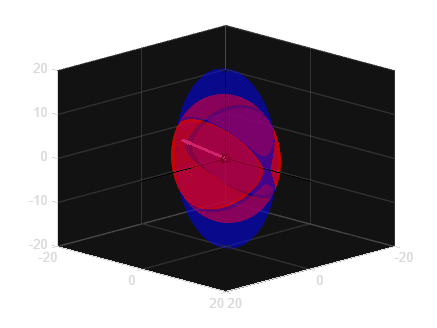

I = [21 0 0; 0 14 0; 0 0 7];
w_0 = [1;10;1];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;0];

out_triint = runModel(I, g, w_0, e, b3_hat);

I1 = I(1, 1);
I2 = I(2, 2);
I3 = I(3, 3);

T = (I1*w_0(1)^2 + I2*w_0(2)^2 + I3*w_0(3)^2)*0.5;
h = (I1^2*w_0(1)^2 + I2^2*w_0(2)^2 + I3^2*w_0(3)^2)^0.5;
Ngrid = 500;
 
w1em = sqrt(2*T/I1); w2em = sqrt(2*T/I2); w3em = sqrt(2*T/I3);
[w1e,w2e,w3e]=ellipsoid(0,0,0,w1em,w2em,w3em,Ngrid);
 
w1hm = h/I1; w2hm = h/I2; w3hm = h/I3;
[w1m,w2m,w3m]=ellipsoid(0,0,0,w1hm,w2hm,w3hm,Ngrid);
 
figure
surf(w1e,w2e,w3e,'FaceColor','r','EdgeColor','none','FaceAlpha',.5)
x = 20;
axis([-x x -x x -x x]);
hold on;

% plot momentum ellipsoid
surf(w1m,w2m,w3m,'FaceColor','b','EdgeColor','none','FaceAlpha',.3)

% plot principal axis vectors
plot3([0 x + 0.5],[0 0],[0 0],'k<')
plot3([0 x + 0.5],[0 0],[0 0],'k-')
plot3([0 0],[0 x + 0.5],[0 0],'k-')
plot3([0 0],[0 x + 0.5],[0 0],'k>')
plot3([0 0],[0 0],[0 x + 0.5],'k-')
plot3([0 0],[0 0],[0 x + 0.5],'k^')

% set the view perspective
view(135,20)

% Initialize the vector as a quiver plot (arrows in 3D)
angular_velocity = out_triint.omega;
num_steps = size(angular_velocity, 1);
h = quiver3(0, 0, 0, angular_velocity(1, 1), angular_velocity(1, 2), angular_velocity(1, 3), 'MaxHeadSize', 0.5, 'LineWidth', 2);

% Animation loop
for t = 2:num_steps
    % Update the vector with new data for this time step
    set(h, 'UData', angular_velocity(t, 1), 'VData', angular_velocity(t, 2), 'WData', angular_velocity(t, 3));
    
    % Pause to control the speed of the animation
    pause(0.001);  % Adjust pause duration to change animation speed
end
hold off;